# Examine Well-Trained Session using Temporal Field Bayes - OutSeq Coding (OLD, DO NOT USE)

% This was the original way I ran the OutSeq coding analysis. I'm keeping it for posterity's sake, but it should not be used
% The issue was that I concatenated a port entry and port exit aligned window for the analysis. This analysis is ok for InSeq as 
%   there is minimal overlap when using the 500ms windows I was using. However, with OutSeq trials it produced extensive overlap
%   to the point where the 'late trial' period, was essentially a duplication of the 'early trial' period's data. The temporal 
%   marginals reflected this very strongly. When the decoding of the 'late trial' period was done without the 'early trial' period
%   data in the training set the ordinal decoding dropped to nearly zero because of the temporal variability

fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

binSize = 200;
dsRate = 50;
trlWindow = {[-500 500]; [-500 500]};
alignment = [{'PokeIn'}, {'PokeOut'}];

bayesType = 1; %1 = Poisson: use with raw spike counts; 2 = Bernoulli: use with binarized spike counts; 3 = Gaussian: Use with z-scored spike counts

numChancePerms = 10;

postCLim = [0 0.05];

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);

%#ok<*UNRCH>


## Compile Data

tic;
for ani = 1:length(fileDirs)
    %% Create & setup initial object and data variables (if initial file)
    mlb = MLB_SM(fileDirs{ani});
    % Create Analysis Variables
    if ani == 1
        % Behavior Variables
        fiscPokeOutLat = cell(length(fileDirs),1);
        fiscRwdDelivLat = cell(length(fileDirs),1);
        oscPokeOutLat = cell(length(fileDirs),1);
        oscRwdDelivLat = cell(length(fileDirs),1);
        % Posteriors
        realPost_TransMat = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        realPost_TransMatERR = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        chancePost_TransMat = cell(mlb.seqLength, mlb.seqLength, numChancePerms, length(fileDirs));
        realPost_TAO = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        chancePost_TAO = cell(mlb.seqLength, mlb.seqLength, numChancePerms, length(fileDirs));
    end
    mlb.binSize = binSize;
    mlb.dsRate = dsRate;
    mlb.windows = trlWindow;
    mlb.alignments = alignment;
    mlb.bayesType = bayesType;

    fiscRwdDelivLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).RewardIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeOutIndex])'/1000;

    %% Analyze things
    mlb.SetLikes_FISC;
    mlb.Process_Observes;
    trlOdrVect = [mlb.trialInfo(mlb.postTrlIDs).Odor];
    trlPosVect = [mlb.trialInfo(mlb.postTrlIDs).Position];
    trlPerfVect = [mlb.trialInfo(mlb.postTrlIDs).Performance];
    tempTmatPosts = cell(mlb.seqLength);
    tempTmatPostsERR = cell(mlb.seqLength);
    tempTaoPosts = cell(mlb.seqLength);
    for odr = 1:mlb.seqLength
        for pos = 1:mlb.seqLength
            curTrlLog = trlOdrVect==odr & trlPosVect==pos & trlPerfVect==1;
            curErrLog = trlOdrVect==odr & trlPosVect==pos & trlPerfVect==0;
            tempTmatPosts{odr,pos} = mlb.post(:,:,curTrlLog);
            tempTmatPostsERR{odr,pos} = mlb.post(:,:,curErrLog);
            if pos~=1 && odr==pos
                for prevOdr = 1:mlb.seqLength
                    if prevOdr~=pos-1 && prevOdr~=pos                                   % This second condition removes skip dupes from the TAO analysis... may be losing significant power?
                        posTAO = find(curTrlLog);
                        prevOdrLog = trlOdrVect(posTAO-1)==prevOdr;
                        tempTaoPosts{prevOdr,pos-1} = mlb.post(:,:,posTAO(prevOdrLog));
                    end
                end
            end
        end
    end
    realPost_TransMat(:,:,ani) = tempTmatPosts;
    realPost_TransMatERR(:,:,ani) = tempTmatPostsERR;
    realPost_TAO(:,:,ani) = tempTaoPosts;
%~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
%     % Process Chance
%     fprintf('.... processing chance....');
%     for perm = 1:numChancePerms 
%         mlb.SetLikes_FISC;
%         tempRealLikes = mlb.likeTrlSpikes;
%         % Permute position ID to disrupt position specific coding
%         chancePerm = permute(reshape(randperm(numel(mlb.fiscTrials)), size(mlb.fiscTrials)), [1,3,2]);
%         tempPosPermLikes = tempRealLikes(chancePerm);
%         % Permute temporal organization to disrupt temporal coding 
%         tempFullPermLikes = tempPosPermLikes;   % Use the position permuted data for the full permutation
%         for t = 1:numel(tempRealLikes)
%             chancePerm = randperm(size(mlb.likeTrlSpikes{t},1));
%             tempFullPermLikes{t} = tempFullPermLikes{t}(chancePerm,:);
%         end
%         mlb.likeTrlSpikes = tempFullPermLikes;
%         mlb.Process_Observes;
%         for odr = 1:mlb.seqLength
%             for pos = 1:mlb.seqLength
%                 curTrlLog = trlOdrVect==odr & trlPosVect==pos & trlPerfVect==1;
%                 chancePost_TransMat{odr,pos,perm,ani} = mlb.post(:,:,curTrlLog);
%                 if pos~=1 && odr==pos
%                     for prevOdr = 1:mlb.seqLength
%                         if prevOdr~=pos-1 && prevOdr~=pos                                   % This second condition removes skip dupes from the TAO analysis... may be losing significant power?
%                             posTAO = find(curTrlLog);
%                             prevOdrLog = trlOdrVect(posTAO-1)==prevOdr;
%                             chancePost_TAO{prevOdr,pos-1,perm,ani} = mlb.post(:,:,posTAO(prevOdrLog));
%                         end
%                     end
%                 end
%             end
%         end
%     end
    fprintf('Complete\n');
end

Compiling StatMatrix Data....Completed


Complete


Compiling StatMatrix Data....Completed


Complete


Compiling StatMatrix Data....Completed


Complete


Compiling StatMatrix Data....Completed


Complete


Compiling StatMatrix Data....Completed


Complete


alignBoundry = find(mlb.decodeIDvects(:,2)==2,1,'first');
alignBoundTime = mlb.decodeIDvects(alignBoundry,1);
nearestPOtime = mlb.decodeIDvects(alignBoundry+(abs(trlWindow{2}(1))/dsRate),1);
rwdDelivLat = cell2mat(fiscRwdDelivLat(:));
nearestRWDtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect<=(nearestPOtime+median(rwdDelivLat)),1,'last'));
piNdx = find(mlb.likeTimeVect==0)+0.5;
poNdx = find(mlb.likeTimeVect==nearestPOtime)+0.5;
rwdNdx = find(mlb.likeTimeVect==nearestRWDtime)+0.5;
posNdx = find(diff(mlb.likeTimeVect)<0)+0.5;
toc

Elapsed time is 37.390279 seconds.


## Combine trials across animals & compute trial marginals

tic;
groupTransMat_Real = cell(mlb.seqLength);
groupTransMat_RealPos = cell(mlb.seqLength);
groupTransMat_RealERR = cell(mlb.seqLength);
groupTransMat_RealPosERR = cell(mlb.seqLength);
groupTransMat_Chance = cell(mlb.seqLength);
groupTransMat_ChancePos = cell(mlb.seqLength);
groupTAO_Real = cell(mlb.seqLength);
groupTAO_RealPos = cell(mlb.seqLength);
groupTAO_Chance = cell(mlb.seqLength);
groupTAO_ChancePos = cell(mlb.seqLength);
for odr = 1:mlb.seqLength
    for pos = 1:mlb.seqLength
        groupTransMat_Real{odr,pos} = cell2mat(realPost_TransMat(odr,pos,:));
        groupTransMat_RealPos{odr,pos} = mlb.TabulateBayesPost(groupTransMat_Real{odr,pos}, mlb.decodeIDvects(:,3));
        groupTransMat_RealERR{odr,pos} = cell2mat(realPost_TransMatERR(odr,pos,:));
        groupTransMat_RealPosERR{odr,pos} = mlb.TabulateBayesPost(groupTransMat_RealERR{odr,pos}, mlb.decodeIDvects(:,3));
        groupTAO_Real{odr,pos} = cell2mat(realPost_TAO(odr,pos,:));
        groupTAO_Real{odr,pos} = mlb.TabulateBayesPost(groupTAO_Real{odr,pos}, mlb.decodeIDvects(:,3));

%         groupTransMat_Chance{odr,pos} = mean(cell2mat(reshape(squeeze(chancePost_TransMat(odr,pos,:,:)), [1,1,numel(chancePost_TransMat(odr,pos,:,:))])),3,'omitnan');
%         groupTransMat_ChancePos{odr,pos} = mean(mlb.TabulateBayesPost(cell2mat(reshape(squeeze(chancePost_TransMat(odr,pos,:,:)), [1,1,numel(chancePost_TransMat(odr,pos,:,:))])), mlb.decodeIDvects(:,3)),3,'omitnan');
%         groupTAO_Chance{odr,pos} = mean(cell2mat(reshape(squeeze(chancePost_TAO(odr,pos,:,:)), [1,1,numel(chancePost_TAO(odr,pos,:,:))])),3,'omitnan');
%         groupTAO_ChancePos{odr,pos} = mean(mlb.TabulateBayesPost(cell2mat(reshape(squeeze(chancePost_TAO(odr,pos,:,:)), [1,1,numel(chancePost_TAO(odr,pos,:,:))])), mlb.decodeIDvects(:,3)),3,'omitnan');
    end
end
toc

Elapsed time is 0.262547 seconds.


## Plot Temporal PDF

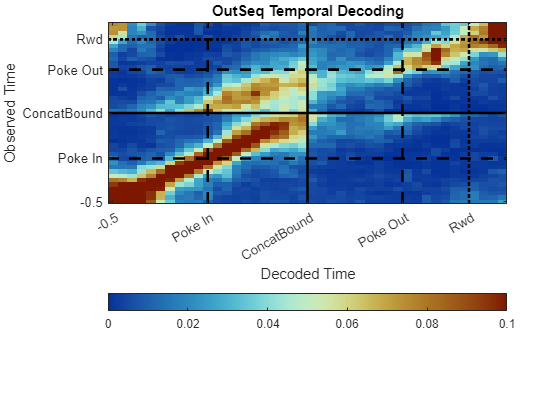

outSeq_PDF = cell2mat(reshape(groupTransMat_Real(~eye(mlb.seqLength)), [1,1,numel(groupTransMat_Real(~eye(mlb.seqLength)))]));
tempTimeDecode = mlb.TabulateBayesPost(outSeq_PDF, mlb.decodeIDvects(:,1));
figure;
imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect, mean(tempTimeDecode,3), postCLim*2);
hold on;
set(gca, 'ydir', 'normal');
colormap(cMap);
title('OutSeq Temporal Decoding');
hold on;
plot(zeros(1,2), get(gca, 'ylim'), '--k', 'linewidth', 2);
plot(repmat(alignBoundTime-0.025, [1,2]), get(gca, 'ylim'), '-k', 'linewidth', 2);
plot(repmat(nearestPOtime-0.025, [1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
plot(repmat(nearestRWDtime-0.025, [1,2]), get(gca, 'ylim'), ':k', 'linewidth', 2);
plot(get(gca, 'xlim'), zeros(1,2), '--k', 'linewidth', 2);
plot(get(gca, 'xlim'), repmat(alignBoundTime-0.025, [1,2]), '-k', 'linewidth', 2);
plot(get(gca, 'xlim'), repmat(nearestPOtime-0.025, [1,2]), '--k', 'linewidth', 2);
plot(get(gca, 'xlim'), repmat(nearestRWDtime-0.025, [1,2]), ':k', 'linewidth', 2);
set(gca, 'xtick', [-0.5 0 alignBoundTime-.025 nearestPOtime-.025, nearestRWDtime-.025], 'xticklabels', [{'-0.5'}, {'Poke In'}, {'ConcatBound'}, {'Poke Out'}, {'Rwd'}],...
    'ytick', [-0.5 0 alignBoundTime-.025 nearestPOtime-.025, nearestRWDtime-.025], 'yticklabels', [{'-0.5'}, {'Poke In'}, {'ConcatBound'}, {'Poke Out'}, {'Rwd'}]);
xlabel('Decoded Time');
ylabel('Observed Time');
colorbar(gca, 'location', 'southoutside');

## Compile OutSeq Odor & Position Probabilities

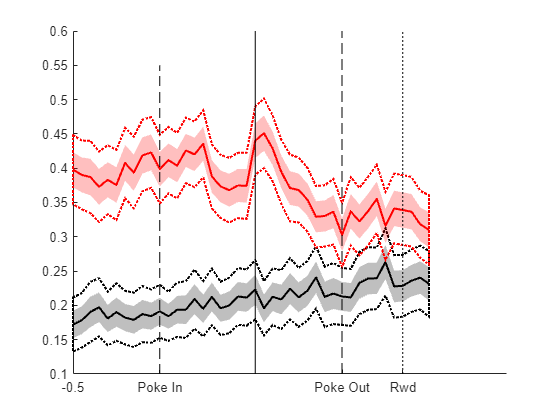

outSeq_OdrProb = cell(mlb.seqLength);
outSeq_PosProb = cell(mlb.seqLength);
tao_OdrProb = cell(mlb.seqLength);
tao_PosProb = cell(mlb.seqLength);
for odr = 1:mlb.seqLength
    for pos = 1:mlb.seqLength
        if odr~=pos
            outSeq_OdrProb{odr,pos} = groupTransMat_RealPos{odr,pos}(:,odr,:);
            outSeq_PosProb{odr,pos} = groupTransMat_RealPos{odr,pos}(:,pos,:);
            tao_OdrProb{odr,pos} = groupTransMat_RealPos{odr,pos}(:,odr,:);
            tao_PosProb{odr,pos} = groupTransMat_RealPos{odr,pos}(:,pos,:);
        end
    end
end
outSeq_OdrProb = cell2mat(reshape(outSeq_OdrProb, [1,1,numel(outSeq_OdrProb)]));
outSeq_PosProb = cell2mat(reshape(outSeq_PosProb, [1,1,numel(outSeq_PosProb)]));
figure; 
mlb.PlotMeanVarLine(mlb.obsvTimeVect, outSeq_OdrProb,3,0.05,'k');
mlb.PlotMeanVarLine(mlb.obsvTimeVect, outSeq_PosProb,3,0.05,'r');
plot([0 0], get(gca,'ylim'), '--k');
plot(repmat(alignBoundTime, [1,2]), get(gca, 'ylim'), '-k');
plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k');
plot(repmat(nearestRWDtime, [1,2]), get(gca, 'ylim'), ':k');
set(gca, 'xtick', [-0.5 0 nearestPOtime, nearestRWDtime], 'xticklabels', [{'-0.5'}, {'Poke In'}, {'Poke Out'}, {'Rwd'}]);